# **目标：搭建整个系统的仿真环境，并测试其误差**

**工作流程:**

**1.在SystemVue中运行DPD Extration流，获得Model System的原始数据**

**2.在MATLAB中开发算法（Alg_PA1），获得应用于实测的模型，并完成仿真**

**3.在SystemVue中运行DPD Validation流，获得Model System的实测数据，对比仿真与实测结果**

一个重要的点——每次的input是固定的，且对于两个system相同。

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Original System----------------------------

此模型是完全固定的！

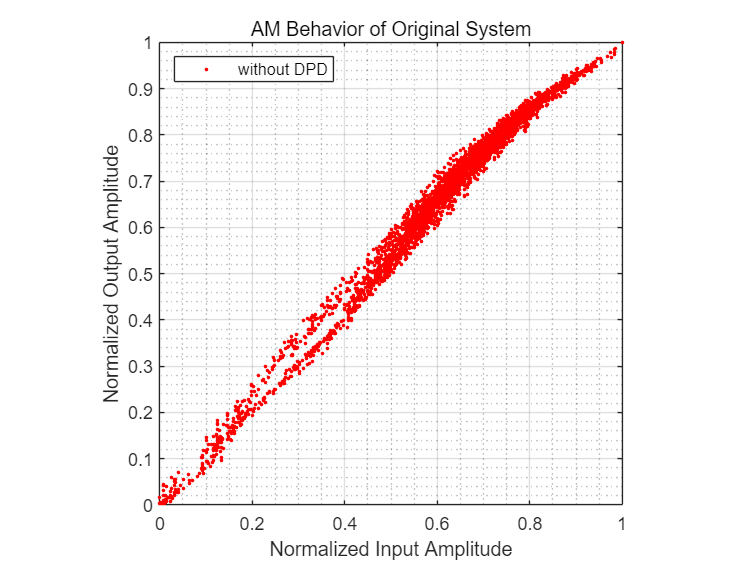

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Original();
Original_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Original_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 模型仿真
[U1,D1]=Power_Divider(Original_input);
U2=PA_1(U1);
U3=PA_3(U2);
D2=PA_2(D1);
D3=PA_4(D2);
Original_output_sim=Power_Combiner(U3,D3);
% 性能评估
err=abs(Original_output_sim-Original_output); %模型本身的误差
Plot_AM(Original_input,Original_output_sim,'AM Behavior of Original System','without DPD');

nmse_sim= NMSE_dB(Original_input,Original_output_sim);
nmse_act = NMSE_dB(Original_input,Original_output);
fprintf('不使用DPD，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

不使用DPD，系统的NMSE仿真结果为 -16.688242 dB


fprintf('不使用DPD，系统的NMSE实测结果为 %f dB\n', nmse_act);

不使用DPD，系统的NMSE实测结果为 -16.688242 dB


## -----------------------------Test System----------------------------

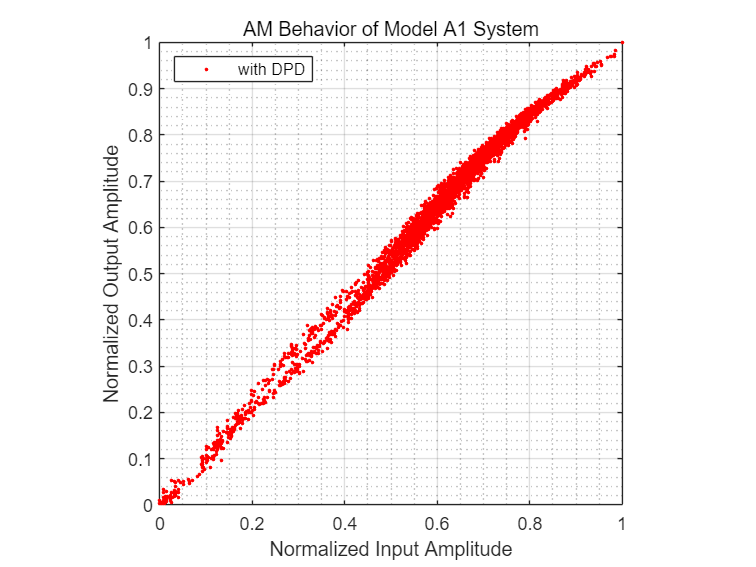

% 读新系统的输出
[Sys_input,Sys_input_r,Sys_input_i]=ReadData(1,'Data_M_A\Sys_input.txt');
[Sys_output,Sys_output_r,Sys_output_i]=ReadData(2,'Data_M_A\Sys_output.txt');

%% 系统模拟
[S_U1,S_D1]=Power_Divider(Sys_input);
S_U1_DPD= DPD_PA1(S_U1,2);
S_U2    = PA_1(S_U1_DPD);
S_U3    = PA_3(S_U2);
S_D2    = PA_2(S_D1);
S_D3    = PA_4(S_D2);
Sys_output_sim=Power_Combiner(S_U3,S_D3);

% 性能评估
err=abs(Sys_output_sim-Sys_output); %模型本身的误差
Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Model A1 System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model A1，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model A1，系统的NMSE仿真结果为 -18.706417 dB


nmse_act= NMSE_dB(Sys_input,Sys_output);
fprintf('使用Model A1，系统的NMSE实测结果为 %f dB\n', nmse_act);

使用Model A1，系统的NMSE实测结果为 -18.706417 dB
